# Project 1: Simulation of 16QAM Modulation

This simulation aims at simulating the 16QAM modulation. The 16QAM is a quadrature modulation scheme, i.e., we have in-phase (real) and quadrature (imaginary) components. Each component is a 4ASK modulation with amplitudes picked from the set $\left\lbrace -3,-1,1,3\right\rbrace$. The project is divided into two stages:

- **Stage 1:** Constructing the transmitter of the 16QAM, exploring the effect of noise on the constellation diagram of the 16QAM, and plotting the power spectral density of the 16QAM signal.

- **Stage 2:** Constructung the receiver of 16QAM, and plotting the BER curve versus $\frac{E_b }{N_0 }$.

## General Logistics of the Project

- The project will be implemented by teams of one or two students.

- Stage 1 of the project will be submitted by Thursday October 31st.

- Stage 2 of the project will be submitted by Monday November 11th.

- You need to submit a viable code that runs without problem.

- You need to submit a report of findings, i.e., figures of constellation at diferent $\frac{E_{b\;} }{N_0 }$ values, PSD of the transmitted signal, BER curve. This is in addition to describing the architecture of the 16QAM receiver you used.

## Stage 1: Constructing 16QAM Modulator Using Quadrature Modulator

We aim at constructing the shown 16QAM modulator in the following figure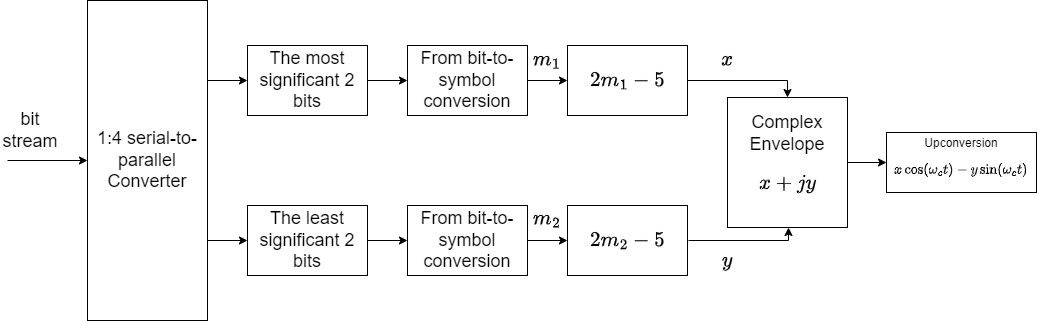 

### For Stage 1, you need to submit the following results

- A viable code of the 16QAM transmitter.

- Plotting the constellation diagram of the 16QAM signal at $\frac{E_b }{N_0 }=0,5,10,15,20$ dB

- Plotting the PSD of the lowpass equivalent of the 16QAM signal.

### Initialization

It is advisable to initialize the code by using 

clc;
clear all;

### System Parameters

It is adviable to collect all controlling parameters of the code at the beginning of the code as follows. In stage 1, the only system paramter is the number of symbols you transmit. The number of bits is 4 times this number for 16QAM. The other parameter is the carrier frequency, which is 1MHz in our project. We use a sampling rate to be three times the carrier frequency. This is in addition to $\frac{E_b }{N_0 }$

Number_symbols=1e6;
Number_bits=4*Number_symbols;
Carrier_frequency=1e6;
Sampling_frequency=3*Carrier_frequency;
Symbol_rate=1e5;
EbN0=10;
BER=[];

### Generating bit stream

Use the function randi to generate a binary vector of length Number_bits

### 1:4 Serial to Parallel Conversion

Use the function reshape to implement the serial to parallel functionality

### From bits-to-symbol Conversion and Symbol Mapping

In this project, we use Gray coding to map the two bits into $m_1 ,m_2 \in \left\lbrace 1,2,3,4\right\rbrace$, i.e., we map the bits such that: $00\to 1,01\to 2,11\to 3,10\to 4$. The outputs $m_1$ and $m_2$ are symbol mapped using the 4ASK symbol mapping rule:


$$\begin{array}{l}
x=2m_1 -5\\
y=2m_2 -5
\end{array}$$


### Complex Envelope and Upconversion

We construct the complex envelope by dealing with the output of branch 1 as the real component (in-phase) and the output of branch 2 as the imaginary component (quadrature) as follows:


$$z=x+j\;y$$


Optionally (You do not need to do that in this project),The complex envelope can be upconverted using the following equation:


$$s\left(t\right)=x\;\mathrm{cos}\;\left(\omega_c t\right)+y\;\mathrm{sin}\;\left(\omega_{c\;} t\right)$$


Where $t$is a vector generated accoding to the sampling rate.

### AWGN and Constellation Diagram

We generate a noise vector in accordance to the $\frac{E_b }{N_0 }\ldotp \;$We first calculate the bit energy of the 16QAM. This can be done from the constellation diagram. This can be done by squaring of the distance of each point from the origin and getting the average and dividing by the number of bits per symbol. Next, we transform the $\frac{E_b }{N_0 }$ into a linear scale according to:


$$\frac{E_b }{N_0 }\left(\mathrm{linear}\right)={10}^{0\ldotp 1*\frac{E_b }{N_0 }\left(\mathrm{dB}\right)}$$


We calculate the corresponding $N_0 \;$from the energy $E_{b\;}$ and $\frac{E_b }{N_0 }\left(\textrm{linear}\right)$.

We generate a random noise vector as a complex Gaussian vector, whose length is the transmitted complex envelope signal and the variance is $\frac{N_0 }{2}$. This can be done using the function randn. We add the noise vector and the transmitted signal vector as:


$$r=z+n$$


We draw the constellation diagram of the vector $r$by the normal plot command or scatter command.

### Plotting the PSD of the Transmitted Signal

You can draw the PSD of the lowpass equivalengt of the transmitted signal by using the periodogram function for example. Another way is to FFT the lowpass signal and square the absolute value to get a power estimate. You need to plot your signal versus a frequency vector.

### Bonuses for Stage 1:

You have multiple bonus points for Stage 1:

- Do the actual upconversion using the carrier.

- Having a slider control for the $\frac{E_b }{N_0 }$ on a live script of MATLAB and by moving the slider, you can show the effect on constealltion live.

## Stage 2: Constructing 16QAM Receiver and BER Curve

In stage 2, we aim at constructing a 16QAM receiver and generate the BER curve. 

### For Stage 2, you need to submit the following results

- A viable code of the 16QAM Receiver.

- Verification of that the Receiver outputs zero error with $N_0 =0$.

- Plotting the BER curve of the 16QAM versus $\frac{E_b }{N_0 }=0:20$ dB compared to the theoretical BER of 16QAM.

### Constructing a 16QAM Receiver

For sanity check, we begin the receiver design by setting $N_0 =0$. This means that the transmission is noiseless and you need to get zero errors if you constructed a valid 16QAM receiver.

One way to construct the receiver is by using the quadrature demapper. To do that, you will have two receiver branches one corresponding to the real part (in-phase) of the received vector $r$ and the other corresponding to the imaginary part (quadrature) of the received vector $r$.


$$\begin{array}{l}
r_1 =\mathrm{Re}\left\lbrace r\right\rbrace \\
r_2 =\mathrm{Im}\left\lbrace r\right\rbrace 
\end{array}$$


Each component is simply a 4ASK signal. Therefore, the receiver is constructed using three thresholds at $\left\lbrace -2,0,2\right\rbrace \ldotp$

You need to reverse all the transmitter blocks to get to the received binary sequence $\hat{\left\lbrace b\right\rbrace } \ldotp$

### Calculating BER

To calculate the BER, you need to compare the original bit sequence from the transmitter $\left\lbrace b\right\rbrace \;$with the recived bit sequence from the output of the receiver $\hat{\left\lbrace b\right\rbrace } \ldotp$ To calculate the BER, we divide errors by the total number of bits Number_bits. This can be done by:

errors=sum(input_bits ~= received_bits);
BER=[BER errors/Number_bits];

You need to draw the BER curve. To do that, you need to loop over the entire code with changing the $\frac{E_b }{N_0 }$ as follows:

EbN0_range=0:20;
for EbNo=EbN0_range
    
    % Insert you code here starting with bit sequence generation and ending
    % by BER calculation
    
    
end

% You draw the BER curve using these lines
semilogy(EbNo_range(1:length(BER)),BER,'linewidth',2,'marker','o');
xlabel('Eb/No (dB)')
ylabel('BER')
hold on
grid on

You need to compare the output curve with the theoretical curve that can be obtained either by drawing the expression from the lectures or using the bertool.

### Bonuses for Stage 2

- Modify the code to generate the BER curve of the QPSK.